# Multiplication of two PDF's

Given two randon variables


$$$${p(x)={1 \over {\sigma \sqrt {2\pi } }}{e^{ - {1 \over 2}{{\left( {{{x - \mu } \over \sigma }} \right)}^2}}}}$$$$


clear
mu_veh=5; std_veh=2
mu_laser=8; std_laser=1
e=linspace(0,40,500)
veh_pdf = normpdf(e,mu_veh,std_veh)
l_pdf = normpdf(e,mu_laser,std_laser)
figure
plot(e,veh_pdf,'b')
hold on
plot(e,l_pdf,'r')
grid on

## PDF multiplication

Computed numerically

PDF_multiplication =veh_pdf.*l_pdf
Area=sum(PDF_multiplication)*40/500
figure
plot(e,veh_pdf)
hold on
plot(e,l_pdf)
plot(e,PDF_multiplication/Area,'g')

## The fusion statistics

See Lecture Note: Understanding the Basis of the Kalman Filter

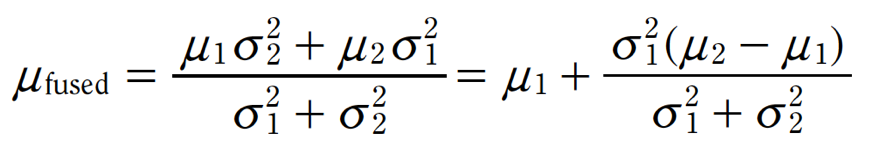

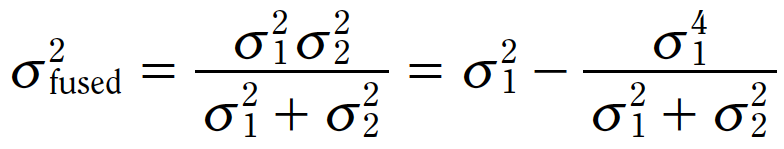

mu_new=mu_veh+(std_veh^2/(std_veh^2+std_laser^2))*(mu_laser-mu_veh);
V_new=(std_veh^2*std_laser^2)/(std_veh^2+std_laser^2);
e = linspace(0,40,500);
figure
hold on
plot(e, gaussfunc(mu_veh, std_veh^2, e), 'b' )
plot(e, gaussfunc(mu_laser, std_laser^2, e), 'r' )
plot(e, gaussfunc(mu_new, V_new, e), 'g' )

## See an animation

figure
e=linspace(0,50,500);
h_veh=[];
h_point=[];
h_fusion=[];
h_rl=[];
h_leg=[];
Initial_position=8;
Initial_std=2
t0=0;
for i=1:100
 delete (h_veh);
 delete (h_point);
 delete (h_rl);
 delete (h_fusion);
 dt=0.1; % seg
 t=i*dt; % seg
 v=2; % m/seg
 position=Initial_position+v*(t-t0);
 std_simu=Initial_std+0.9*(t-t0); % Emulating how the uncertanty increase
 %e=linspace(0,40,500);
 h_veh=plot(e, gaussfunc(position, std_simu^2, e), 'b' );
 hold on
 h_point=scatter(position,0,40);
 h_point.LineWidth = 0.6;
 h_point.MarkerEdgeColor = 'b';
 h_point.MarkerFaceColor = [0 0.5 0.5];

 axis([0 50 0 0.8]);
 h_leg=legend([h_veh h_point],{'Robot-PDF','Robot-Position'})
 title(h_leg,'Who is who')
 set(h_leg,'FontSize',20);
 if (i>50) && (i<52)
  h_rl=plot(e, gaussfunc(position+mu_laser, std_laser^2, e), 'r' ); % plot measurement
  h_fusion=plot(e, gaussfunc(position+mu_new, V_new, e), 'g' ); % plot the fused information
  h_leg=legend([h_veh h_rl h_fusion],{'Robot-PDF','Laser-PDF','Fusion'});
  title(h_leg,'Who is who');
  set(h_leg,'FontSize',20);
  pause(3);
  delete (h_veh);
  delete (h_rl);
  Initial_position=position+mu_new;
  Initial_std=sqrt(V_new);
  t0=50*dt;
 end
 pause(0.2);
end

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Robot-Position'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.5768 0.7083 0.3143 0.1988]
          Units: 'normalized'

  Show all properties

h_leg =   Legend (Who is who) with properties:

         String: {'Robot-PDF'  'Laser-PDF'  'Fusion'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 20
       Position: [0.6357 0.6476 0.2554 0.2595]
          Units: 'normalized'

  Show all properties